clear;close;clc;

% Track parameters
trackWidth = 0.2; % Constant width on both sides of the centerline

% Waypoints along the track centerline
waypoints = [
    0, 0;
    1, 0;
    1.5, 0;
    2, 0;
    2.5, 1;
    2.5, 2;
    2, 3;
    2, 5;
    0.5, 3.5;
    0.5, 3;
    0, 2.5;
    -1 1.8;
    -2, 1.8;
    -2.5, 1;
    -2, 0.1;
    -1, 0;
    -0, 0;
    0, 0;
];


numPoints = 100;

% Interpolate centerline using cubic spline
tValues = linspace(0, 1, size(waypoints, 1));
tqValues = linspace(0, 1, numPoints);

centerlineX = spline(tValues, waypoints(:, 1), tqValues)';
centerlineY = spline(tValues, waypoints(:, 2), tqValues)';
centerline = [centerlineX, centerlineY]';

centerlineDirection = [[1;0] diff(centerline, 1, 2)];
centerlineDirection=centerlineDirection ./ vecnorm(centerlineDirection);

centerlineNormalDirection = [centerlineDirection(2, :); -centerlineDirection(1, :)];
centerlineNormalDirection = centerlineNormalDirection ./ vecnorm(centerlineNormalDirection);

leftBoundary = centerline(:, 1:end) - trackWidth * centerlineNormalDirection;
rightBoundary = centerline(:, 1:end) + trackWidth * centerlineNormalDirection;


% Calculate the first derivatives
dx_dt = [0 diff(centerline(1, :), 1, 2)];
dy_dt = [0 diff(centerline(2, :), 1, 2)];

% Compute the tangent vectors T by normalizing the first derivatives
tangent_lengths = sqrt(dx_dt.^2 + dy_dt.^2);
tangent_vectors = [dx_dt./tangent_lengths; dy_dt./tangent_lengths];

% Calculate the second derivatives
d2x_dt2 = [0 diff(tangent_vectors(1, :), 1, 2)];
d2y_dt2 = [0 diff(tangent_vectors(2, :), 1, 2)];

% Compute the curvature k as the magnitude of d2x_dt2 and d2y_dt2 divided by the square of the tangent_lengths
curvature = sqrt(d2x_dt2.^2 + d2y_dt2.^2) ./ (tangent_lengths(1:end).^2);

% Compute the total distance of the track
totalDistance = sum(sqrt(sum(diff(centerline).^2, 2)));

progress=linspace(0,totalDistance,numPoints);

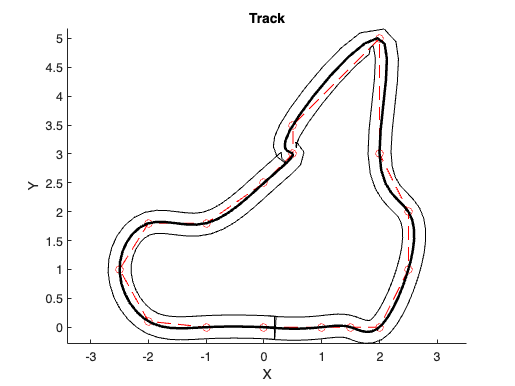

% Plot the track
figure;
hold on;
plot(waypoints(:, 1), waypoints(:, 2), 'ro--');
plot(centerline(1, :), centerline(2, :), 'k-', 'LineWidth', 2);
plot(leftBoundary(1, :), leftBoundary(2, :), 'k-');
plot(rightBoundary(1, :), rightBoundary(2, :), 'k-');
axis equal;
xlabel('X');
ylabel('Y');
title('Track');
hold off;

% Save track data
save('track.mat', ...
    'trackWidth', 'centerline', 'totalDistance', 'progress', ...
    'centerlineDirection', 'centerlineNormalDirection', 'curvature', ...
    'leftBoundary', 'rightBoundary');


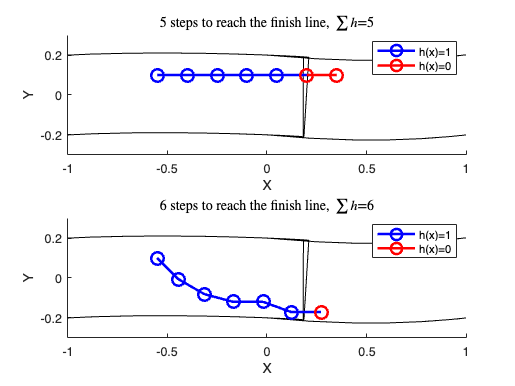

% h
startPoint=[-0.55 0.1]';
ds=0.15;
vec=@(a)[cos(a) sin(a)]'.*ds;
steps=7;

angle1=deg2rad([0 0 0 0 0 0]);
angle2=deg2rad([-45 -30 -15 0 -20 0]);

traj1=[startPoint];
traj2=[startPoint];
for i=1:steps-1
    traj1=[traj1 traj1(:,end)+vec(angle1(i))];
    traj2=[traj2 traj2(:,end)+vec(angle2(i))];
end

figure;

subplot(2,1,1)
hold on;
plot(leftBoundary(1, :), leftBoundary(2, :), 'k-','HandleVisibility','off');
plot(rightBoundary(1, :), rightBoundary(2, :), 'k-','HandleVisibility','off');
plot(traj1(1,1:6), traj1(2,1:6), '-ob', ...
    'LineWidth',2,'MarkerSize',10, ...
    'DisplayName',"h(x)=1");
plot(traj1(1,6:7), traj1(2,6:7), '-or', ...
    'LineWidth',2,'MarkerSize',10, ...
     'DisplayName',"h(x)=0");
axis equal;
axis([-1 1 -0.3 0.3])
xlabel('X');
ylabel('Y');
legend
title("5 steps to reach the finish line, $\sum h$=5",'Interpreter','latex')
hold off;

subplot(2,1,2)
hold on;
plot(leftBoundary(1, :), leftBoundary(2, :), 'k-','HandleVisibility','off');
plot(rightBoundary(1, :), rightBoundary(2, :), 'k-','HandleVisibility','off');
plot(traj2(1,1:7), traj2(2,1:7), '-ob', ...
    'LineWidth',2,'MarkerSize',10, ...
     'DisplayName',"h(x)=1");
plot(traj2(1,7), traj2(2,7), '-or', ...
    'LineWidth',2,'MarkerSize',10, ...
     'DisplayName',"h(x)=0");
axis equal;
axis([-1 1 -0.3 0.3])
xlabel('X');
ylabel('Y');
legend
title("6 steps to reach the finish line, $\sum h$=6",'Interpreter','latex')
hold off;